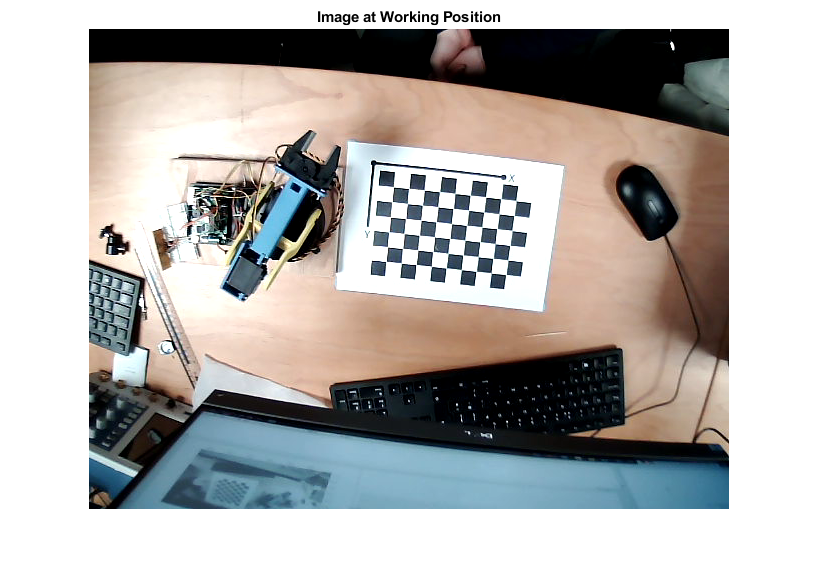

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This code is to extract the checkerboad points USING THE REAL CHECKERBOARD %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% General Settings
numImages = 7; % depends on the number of images you have
squareSize = 21; % in millimeters (actual measured)
% Read files
files = cell(1, numImages);
for i = 1:numImages
 files{i} = fullfile(sprintf('Image%d.png', i-1));
end
% Display the image at working position
I = imread(files{1}); % assume image1 is the working position
figure; imshow(I);
title('Image at Working Position');

% Detect the checkerboard corners in the images.
[imagePoints, boardSize] = detectCheckerboardPoints(files(1:7))

imagePoints = imagePoints(:,:,1) =

  305.3527  158.6530
  303.8606  173.6556
  302.4030  188.8427
  300.9289  203.7880
  299.5069  218.7145
  298.0084  233.3454
  320.7894  160.1944
  319.2460  175.2862
  317.7193  190.2901
  316.1695  205.3493
  314.6747  220.2987
  313.1521  234.9017
  336.1693  161.8229
  334.5798  176.9754
  332.9300  191.9507
  331.2712  207.0503
  329.7627  221.9183
  328.1244  236.4622
  351.6276  163.4827
  349.9332  178.7390
  348.1139  193.7020
  346.4312  208.7993
  344.8395  223.5210
  343.2537  238.0997
  366.9966  165.2016
  365.1917  180.3241
  363.6001  195.4786
  361.8319  210.2939
  360.0124  225.1598
  358.1696  239.8904
  382.2813  166.9928
  380.6065  182.0252
  378.8415  197.1518
  376.9277  212.0056
  375.0482  226.8564
  373.3288  241.4835
  397.7993  168.8413
  395.9037  183.8675
  393.9767  198.8898
  392.0600  213.7395
  390.1869  228.6330
  388.2464  243.1859
  412.9499  170.5801
  411.0557  185.7238
  409.0468  200.4671
  407.1643  215.556

boardSize =      7    10





files

files = 1×7 cell array
    {'Image0.png'}    {'Image1.png'}    {'Image2.png'}    {'Image3.png'}    {'Image4.png'}    {'Image5.png'}    {'Image6.png'}


size(imagePoints)

ans =     54     2     7


% Generate the world coordinates of the checkerboard corners in the
% pattern-centric coordinate system, with the upper-left corner at (0,0).
worldPoints = generateCheckerboardPoints(boardSize, squareSize)

worldPoints =      0     0
     0    21
     0    42
     0    63
     0    84
     0   105
    21     0
    21    21
    21    42
    21    63



size(imagePoints)

ans =     54     2     7


Phi = zeros(54*2,9,numImages);      % Phi matrix
H = zeros(3,3,numImages);           % H matrix

for j = 1:1:numImages

    for i = 1:1:54          % This for loop fills out the Phi matrix with the values from the 54 sets
                            % of coordinate points for each of the 7 images
        Phi(2*i-1,6,j) = 1;
        Phi(2*i,3,j) = 1;
        X = worldPoints(i,1);
        Y = worldPoints(i,2);
        x = imagePoints(i,1,j);
        y = imagePoints(i,2,j);
        Phi(2*i-1,4,j) = X;
        Phi(2*i,1,j) = X;
        Phi(2*i-1,5,j) = Y;
        Phi(2*i,2,j) = Y;
        
        Phi(2*i-1,7,j) = -y*X;
        Phi(2*i-1,8,j) = -y*Y;
        Phi(2*i-1,9,j) = -y;
        Phi(2*i,7,j) = -x*X;
        Phi(2*i,8,j) = -x*Y;
        Phi(2*i,9,j) = -x;
        
    end
    
    [~,~,V] = svd(Phi(:,:,j));
    % Use the SVD function to calculate the h vector for each image
    
    V(:,9);
    
    H(1,1:3,j) = V(1:3,9); % Assign values to each image's associated H matrix using the h vector
    H(2,1:3,j) = V(4:6,9);
    H(3,1:3,j) = V(7:9,9);
    
end

Phi

Phi = Phi(:,:,1) =

   1.0e+04 *

         0         0         0         0         0    0.0001         0         0   -0.0159
         0         0    0.0001         0         0         0         0         0   -0.0305
         0         0         0         0    0.0021    0.0001         0   -0.3647   -0.0174
         0    0.0021    0.0001         0         0         0         0   -0.6381   -0.0304
         0         0         0         0    0.0042    0.0001         0   -0.7931   -0.0189
         0    0.0042    0.0001         0         0         0         0   -1.2701   -0.0302
         0         0         0         0    0.0063    0.0001         0   -1.2839   -0.0204
         0    0.0063    0.0001         0         0         0         0   -1.8959   -0.0301
         0         0         0         0    0.0084    0.0001         0   -1.8372   -0.0219
         0    0.0084    0.0001         0         0         0         0   -2.5159   -0.0300
         0         0         0         0    0.0105    0.

H

H = H(:,:,1) =

    0.0022   -0.0000    0.8878
    0.0003    0.0022    0.4602
    0.0000    0.0000    0.0029


H(:,:,2) =

    0.0038   -0.0003    0.8728
    0.0002    0.0036    0.4881
    0.0000   -0.0000    0.0036


H(:,:,3) =

    0.0002    0.0026   -0.9711
   -0.0023    0.0001   -0.2385
    0.0000    0.0000   -0.0025


H(:,:,4) =

    0.0022   -0.0009   -0.9075
    0.0003    0.0013   -0.4200
    0.0000   -0.0000   -0.0021


H(:,:,5) =

   -0.0002   -0.0028   -0.8235
    0.0026   -0.0004   -0.5673
    0.0000   -0.0000   -0.0026


H(:,:,6) =

   -0.0029    0.0012   -0.9400
   -0.0006   -0.0023   -0.3411
    0.0000    0.0000   -0.0029


H(:,:,7) =

    0.0005    0.0022   -0.9624
   -0.0013    0.0002   -0.2715
    0.0000    0.0000   -0.0022



B = zeros(3,3)          % B matrix

B =      0     0     0
     0     0     0
     0     0     0


V = zeros(numImages*2,6)         % V matrix

V =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


v = zeros(1,6,2,2,numImages)    % v matrix - Will store the 1x6 v11T, v12T and v21T matrices for each of the 7 images

v = v(:,:,1,1,1) =

     0     0     0     0     0     0


v(:,:,2,1,1) =

     0     0     0     0     0     0


v(:,:,1,2,1) =

     0     0     0     0     0     0


v(:,:,2,2,1) =

     0     0     0     0     0     0


v(:,:,1,1,2) =

     0     0     0     0     0     0


v(:,:,2,1,2) =

     0     0     0     0     0     0


v(:,:,1,2,2) =

     0     0     0     0     0     0


v(:,:,2,2,2) =

     0     0     0     0     0     0


v(:,:,1,1,3) =

     0     0     0     0     0     0


v(:,:,2,1,3) =

     0     0     0     0     0     0


v(:,:,1,2,3) =

     0     0     0     0     0     0


v(:,:,2,2,3) =

     0     0     0     0     0     0


v(:,:,1,1,4) =

     0     0     0     0     0     0


v(:,:,2,1,4) =

     0     0     0     0     0     0


v(:,:,1,2,4) =

     0     0     0     0     0     0


v(:,:,2,2,4) =

     0     0     0     0     0     0


v(:,:,1,1,5) =

     0     0     0     0     0     0


v(:,:,2,1,5) =

     0     0     0     0     0     0


v(:,:,

% First two arguments, dimensions of the v11T/v12T/v21T vectors.
% Third and fourth arguments, 2x2 to access the v11T, v12T or V21T matrices.
% Fifth argument - 6 elements associated with each of the 7 images.
for k = 1:1:numImages
    for j = 1:1:2   % These for loops calculate the values in the v11T/v12T/v21T vectors for all 7 images.
        for i = 1:1:2
            v(1,1,i,j,k) = H(1,i,k)*H(1,j,k);
            v(1,2,i,j,k) = H(2,i,k)*H(1,j,k)+H(1,i,k)*H(2,j,k);
            v(1,3,i,j,k) = H(2,i,k)*H(2,j,k);
            v(1,4,i,j,k) = H(3,i,k)*H(1,j,k)+H(1,i,k)*H(3,j,k);
            v(1,5,i,j,k) = H(3,i,k)*H(2,j,k)+H(2,i,k)*H(3,j,k);
            v(1,6,i,j,k) = H(3,i,k)*H(3,j,k);
        end
    end
    V(2*k-1,:) = v(1,:,1,2,k);  % Stack the matrix with several Hs from the different images
    V(2*k,:) = v(1,:,1,1,k) - v(1,:,2,2,k);
end
v

v = v(:,:,1,1,1) =

   1.0e-05 *

    0.4748    0.1145    0.0069    0.0001    0.0000    0.0000


v(:,:,2,1,1) =

   1.0e-05 *

   -0.0032    0.4842    0.0584    0.0001    0.0000    0.0000


v(:,:,1,2,1) =

   1.0e-05 *

   -0.0032    0.4842    0.0584    0.0001    0.0000    0.0000


v(:,:,2,2,1) =

   1.0e-05 *

    0.0000   -0.0065    0.4946   -0.0000    0.0003    0.0000


v(:,:,1,1,2) =

   1.0e-04 *

    0.1420    0.0118    0.0002    0.0000    0.0000    0.0000


v(:,:,2,1,2) =

   1.0e-04 *

   -0.0095    0.1367    0.0057   -0.0000    0.0000   -0.0000


v(:,:,1,2,2) =

   1.0e-04 *

   -0.0095    0.1367    0.0057   -0.0000    0.0000   -0.0000


v(:,:,2,2,2) =

   1.0e-04 *

    0.0006   -0.0183    0.1324    0.0000   -0.0000    0.0000


v(:,:,1,1,3) =

   1.0e-05 *

    0.0025   -0.0726    0.5272    0.0000   -0.0003    0.0000


v(:,:,2,1,3) =

   1.0e-05 *

    0.0412   -0.5964   -0.0202    0.0002   -0.0001    0.0000


v(:,:,1,2,3) =

   1.0e-05 *

    0.0412   -0.5964   -0.0202    0.

V

V = 	1.0e+-4 *

   -0.0003    0.0484    0.0058    0.0000    0.0000    0.0000
    0.0475    0.0121   -0.0488    0.0000   -0.0000   -0.0000
   -0.0095    0.1367    0.0057   -0.0000    0.0000   -0.0000
    0.1413    0.0301   -0.1322    0.0000    0.0000   -0.0000
    0.0041   -0.0596   -0.0020    0.0000   -0.0000    0.0000
   -0.0675   -0.0118    0.0526   -0.0000   -0.0000    0.0000
   -0.0191    0.0262    0.0041   -0.0000   -0.0000   -0.0000
    0.0413    0.0366   -0.0161   -0.0000    0.0001   -0.0000
    0.0066   -0.0732   -0.0105   -0.0000   -0.0000   -0.0000
   -0.0801   -0.0349    0.0666   -0.0000    0.0000   -0.0000



[~,~,V] = svd(V)    % Use the SVD function to calculate the b vector

V =     0.6931   -0.3273    0.6422    0.0003    0.0018   -0.0000
    0.4267    0.9044    0.0005    0.0003    0.0000    0.0000
   -0.5810    0.2737    0.7665    0.0004    0.0017   -0.0000
    0.0000   -0.0003    0.0010    0.8174   -0.5761    0.0007
    0.0003    0.0001    0.0023   -0.5761   -0.8174    0.0003
   -0.0000   -0.0000   -0.0000    0.0003   -0.0007   -1.0000



b = V(:,6)

b =    -0.0000
    0.0000
   -0.0000
    0.0007
    0.0003
   -1.0000



B(1,1) = b(1,1);    % Fill the symmetric B matrix with the b vector
B(1,2) = b(2,1);
B(1,3) = b(4,1);
B(2,1) = b(2,1);
B(2,2) = b(3,1);
B(2,3) = b(5,1);
B(3,1) = b(4,1);
B(3,2) = b(5,1);
B(3,3) = b(6,1)

B =    -0.0000    0.0000    0.0007
    0.0000   -0.0000    0.0003
    0.0007    0.0003   -1.0000



% Calculate the intrinsic parameters
y0 = (B(1,2)*B(1,3)-B(1,1)*B(2,3))/(B(1,1)*B(2,2)-B(1,2)*B(1,2))

y0 = 190.3017

lambda = B(3,3) - ( ( B(1,3)*B(1,3) + y0*(B(1,2)*B(1,3)-B(1,1)*B(2,3)) ) / B(1,1) )

lambda = -0.6854

alpha = sqrt(lambda/B(1,1))

alpha = 616.9655

beta = sqrt((lambda*B(1,1))/(B(1,1)*B(2,2)-B(1,2)*B(1,2)))

beta = 615.0253

gamma = -((B(1,2)*alpha*alpha*beta)/(lambda))

gamma = 2.0600

x0 = (gamma*y0/alpha) - (B(1,3)*alpha*alpha/lambda)

x0 = 372.5300


K = zeros(3,3); % Fill the K matrix with the intrinsic parameters
K(1,1) = alpha;
K(1,2) = gamma;
K(1,3) = x0;
K(2,2) = beta;
K(2,3) = y0;
K(3,3) = 1

K =   616.9655    2.0600  372.5300
         0  615.0253  190.3017
         0         0    1.0000



% Calibrate the camera using Matlab’s toolbox.
imageSize = [size(I, 1), size(I, 2)];
cameraParams = estimateCameraParameters(imagePoints, worldPoints, ...
 'ImageSize', imageSize);

ToolboxParameters = cameraParams.Intrinsics.IntrinsicMatrix'

ToolboxParameters =   628.4708         0  342.2602
         0  625.7525  184.1812
         0         0    1.0000



% Calculate the extrinsic parameters
sigma = 1/norm(K\H(1:3,1,1))

sigma = 2.8741e+05

r1 = sigma*(K\H(1:3,1,1))

r1 =     0.9931
    0.1117
    0.0357


r2 = sigma*(K\H(1:3,2,1))

r2 =    -0.1209
    0.9826
    0.1834


r3 = cross(r1,r2)

r3 =    -0.0146
   -0.1864
    0.9893



R = [r1 r2 r3]

R =     0.9931   -0.1209   -0.0146
    0.1117    0.9826   -0.1864
    0.0357    0.1834    0.9893



CPWorg = sigma*(K\H(1:3,3,1))

CPWorg =   -90.7876
  -43.4516
  835.5302



% Compare our extrinsic parameter values with the Toolbox values
ToolboxRotation = cameraParams.RotationMatrices(:,:,1)'

ToolboxRotation =     0.9938   -0.1100    0.0158
    0.1112    0.9827   -0.1484
    0.0008    0.1492    0.9888


ToolboxTranslation = cameraParams.TranslationVectors(1,:)'

ToolboxTranslation =   -49.8549
  -35.0312
  853.1106



K_Lab = K

K_Lab =   616.9655    2.0600  372.5300
         0  615.0253  190.3017
         0         0    1.0000


% Save the intrinsic parameter matrix
save('K_Lab.mat','K_Lab')

% Fill and save the extrinsic parameter matrix
Tcw = zeros(4,4);
Tcw(1:3,1:3) = R;
Tcw(1:3,4) = CPWorg;
Tcw(4,4) = 1;

Tcw_Lab = Tcw

Tcw_Lab =     0.9931   -0.1209   -0.0146  -90.7876
    0.1117    0.9826   -0.1864  -43.4516
    0.0357    0.1834    0.9893  835.5302
         0         0         0    1.0000



save('Tcw_Lab.mat', 'Tcw_Lab')